# Hierachical NSOLT dictionary learning 

Please do not forget to run** setpath **in the top directory of this package, and then return to this directory.

Requirements: MATLAB R2021a

 Contact address: Shogo MURAMATSU,

        Faculty of Engineering, Niigata University,

        8050 2-no-cho Ikarashi, Nishi-ku,

        Niigata, 950-2181, JAPAN

        [http://msiplab.eng.niigata-u.ac.jp](http://msiplab.eng.niigata-u.ac.jp)  

 Copyright (c) 2020, Shogo MURAMATSU, All rights reserved.

## Preparation

clear 
close all
support.fcn_download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


## Bivariate lattice-structure oversampled filter banks 

As an example, let us adopt a non-separable oversampled lapped transform (NSOLT) of  type-I with the number of channels (the numbers of even and odd symmetric channels are identical to each other) and polyphase order (even):

        
$$\mathbf{E}(z_\mathrm{v},z_\mathbf{h})
=
\left(\prod_{k_\mathrm{h}=1}^{N_\mathrm{h}/2}
{\mathbf{V}_{2k_\mathrm{h}}^{\{\mathrm{h}\}}}\bar{\mathbf{Q}}(z_\mathrm{h}){\mathbf{V}_{2k_\mathrm{h}-1}^{\{\mathrm{h}\}}}{\mathbf{Q}}(z_\mathrm{h})\right)
%
\left(\prod_{k_{\mathrm{v}}=1}^{N_\mathrm{v}/2}{\mathbf{V}_{2k_\mathrm{v}}^{\{\mathrm{v}\}}}\bar{\mathbf{Q}}(z_\mathrm{v}){\mathbf{V}_{2k_\mathrm{v}-1}^{\{\mathrm{v}\}}}{\mathbf{Q}}(z_\mathrm{v})\right)
%
\mathbf{V}_0\mathbf{E}_0,$$


        
$$\mathbf{R}(z_\mathrm{v},z_\mathbf{h})
=\mathbf{E}^T(z_\mathrm{v}^{-1},z_\mathrm{h}^{-1}),$$


where

- $\mathbf{E}(z_\mathrm{v},z_\mathrm{h})$:  Type-I polyphase matrix of the analysis filter bank

- $\mathbf{R}(z_\mathrm{v},z_\mathrm{h})$: Type-II polyphase matrix in the synthesis filter bank

- $z_d\in\mathbb{C}, d\in\{\mathrm{v},\mathrm{h}\}$: The parameter of Z-transformation direction

- $N_d\in \mathbb{N}, d\in\{\mathrm{v},\mathrm{h}\}$: Polyphase order in direction $d$ (number of overlapping blocks)

- $\mathbf{V}_0=\left(\begin{array}{cc}\mathbf{W}_{0} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_0\end{array}\right)
%
\left(\begin{array}{c}\mathbf{I}_{M/2} \\ 
\mathbf{O} \\
\mathbf{I}_{M/2} \\
\mathbf{O}
\end{array}\right)\in\mathbb{R}^{P\times M}$,$\mathbf{V}_n^{\{d\}}=\left(\begin{array}{cc}\mathbf{I}_{P/2} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_n^{\{d\}}\end{array}\right)\in\mathbb{R}^{P\times P}, d\in\{\mathrm{v},\mathrm{h}\}$, where$\mathbf{W}_0, \mathbf{U}_0,\mathbf{U}_n^{\{d\}}\in\mathbb{R}^{P/2\times P/2}$are orthonromal matrices.

- $\mathbf{Q}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  z^{-1}\mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\bar{\mathbf{Q}}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} z\mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  \mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\mathbf{B}_{P}=\frac{1}{\sqrt{2}}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{I}_{P/2} \\ \mathbf{I}_{P/2} &  -\mathbf{I}_{P/2}\end{array}\right)$

【References】 

- MATLAB SaivDr Package: [https://github.com/msiplab/SaivDr](https://github.com/msiplab/SaivDr)

- S. Muramatsu, K. Furuya and N. Yuki, "Multidimensional Nonseparable Oversampled Lapped Transforms: Theory and Design," in IEEE Transactions on Signal Processing, vol. 65, no. 5, pp. 1251-1264, 1 March1, 2017, doi: 10.1109/TSP.2016.2633240.

- S. Muramatsu, T. Kobayashi, M. Hiki and H. Kikuchi, "Boundary Operation of 2-D Nonseparable Linear-Phase Paraunitary Filter Banks," in IEEE Transactions on Image Processing, vol. 21, no. 4, pp. 2314-2318, April 2012, doi: 10.1109/TIP.2011.2181527.

- S. Muramatsu, M. Ishii and Z. Chen, "Efficient parameter optimization for example-based design of nonseparable oversampled lapped transform," 2016 IEEE International Conference on Image Processing (ICIP), Phoenix, AZ, 2016, pp. 3618-3622, doi: 10.1109/ICIP.2016.7533034.

- Furuya, K., Hara, S., Seino, K., & Muramatsu, S. (2016). Boundary operation of 2D non-separable oversampled lapped transforms. *APSIPA Transactions on Signal and Information Processing, 5*, E9. doi:10.1017/ATSIP.2016.3.

## Hierachical decomposition for 2-D Grayscale image

Let $R_M^P(\tau)$ be the redundancy of $\tau$-level tree-structured filter bank, then we have the relation 

    
$$R_M^P(\tau)=\left\{\begin{array}{ll} (P-1)\tau + 1, & M=1, \\ \frac{P-1}{M-1}-\frac{P-M}{(M-1)M^\tau}, & M\geq 2.\end{array}\right.$$


% Decimation factor (Strides)
decFactor = [2 2]; % [My Mx]

% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [1 1] * 4% [Ps Pa] (Ps=Pa)

nChannels =      4     4


% Number of tree levels
nLevels = 3

nLevels = 3


% Redundancy
P = sum(nChannels);
M = prod(decFactor);
redundancy = ...
    (prod(decFactor)==1)*((P-1)*nLevels+1) + ...
    (prod(decFactor)>1)*((P-1)/(M-1)-(P-M)/((M-1)*M^nLevels))

redundancy = 2.3125


% Polyphase Order
ppOrder = [1 1] *4

ppOrder =      4     4



% Sparsity ratio
sparsityRatio = 1/16;

% Number of patchs per image
nSubImgs = 128;

% No DC-leakage
noDcLeakage = true

noDcLeakage = logical
   1


Setting of dictionary update step

% Number of iterations
nIters = 8;

% Standard deviation of initial angles
stdInitAng = pi/6; 

% Patch size for training
szPatchTrn = [64 64]; % > [ (Ny+1)My (Nx+1)Mx ]

% Mini batch size
miniBatchSize = 32;

% Number of Epochs (1 Epoch = nSubImgs/miniBachSize iterlations)
maxEpochs = 32; 

% Number of iterations
maxIters = nSubImgs/miniBatchSize * maxEpochs

maxIters = 128

% Training options
opts = trainingOptions('sgdm', ... % Stochastic gradient descent w/ momentum
    ...'Momentum', 0.9000,...
    ...'InitialLearnRate',0.0100,...
    ...'LearnRateScheduleSettings','none',...
    'L2Regularization',0.0,...1.0000e-04,... % Set zero since parameters are rotaion angles.
    ...'GradientThresholdMethod','l2norm',...
    ...'GradientThreshold',Inf,...
    'MaxEpochs',maxEpochs,...30,...
    'MiniBatchSize',miniBatchSize,...128,...
    'Verbose',1,...
    'VerboseFrequency',32,...50,...
    ...'ValidationData',[],...
    ...'ValidationFrequency',50,...
    ...'ValidationPatience',Inf,...
    ...'Shuffle','once',...
    ...'CheckpointPath','',...
    ...'ExecutionEnvironment','auto',...
    ...'WorkerLoad',[],...
    ...'OutputFcn',[],...
    'Plots','none',...'training-progress',...
    ...'SequenceLength','longest',...
    ...'SequencePaddingValue',0,...
    ...'SequencePaddingDirection','right',...
    ...'DispatchInBackground',0,...
    'ResetInputNormalization',0);...1

## Construction of layers

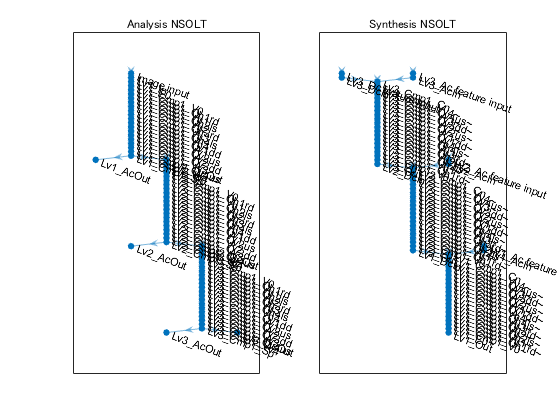

import saivdr.dcnn.*
analysislgraph = fcn_creatensoltlgraph2d([],...
    'InputSize',szPatchTrn,...
    'NumberOfChannels',nChannels,...
    'DecimationFactor',decFactor,...
    'PolyPhaseOrder',ppOrder,...
    'NumberOfLevels',nLevels,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Analyzer');
synthesislgraph= fcn_creatensoltlgraph2d([],...
    'InputSize',szPatchTrn,...
    'NumberOfChannels',nChannels,...
    'DecimationFactor',decFactor,...
    'PolyPhaseOrder',ppOrder,...
    'NumberOfLevels',nLevels,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Synthesizer');

figure(3)
subplot(1,2,1)
plot(analysislgraph)
title('Analysis NSOLT')
subplot(1,2,2)
plot(synthesislgraph)

title('Synthesis NSOLT')

% Construction of deep learning network.
synthesisnet = dlnetwork(synthesislgraph);

% Initialize
nLearnables = height(synthesisnet.Learnables);
for iLearnable = 1:nLearnables
    if synthesisnet.Learnables.Parameter(iLearnable)=="Angles"
        synthesisnet.Learnables.Value(iLearnable) = ...
            cellfun(@(x) x+stdInitAng*randn(size(x)), ...
            synthesisnet.Learnables.Value(iLearnable),'UniformOutput',false);
    end
end

% Copy the synthesizer's parameters to the analyzer
synthesislgraph = layerGraph(synthesisnet);

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

analysislgraph = fcn_cpparamssyn2ana(analysislgraph,synthesislgraph);
analysisnet = dlnetwork(analysislgraph);

### Confirmation of the adjoint relation (perfect reconstruction)


nOutputs = nLevels+1;

x = rand(szPatchTrn,'single');
dls = cell(1,nOutputs);
dlx = dlarray(x,'SSCB'); % Deep learning array (SSCB: Spatial,Spatial,Channel,Batch)
[dls{1:nOutputs}] = analysisnet.predict(dlx);
dly = synthesisnet.predict(dls{1:nOutputs});
display("MSE: " + num2str(mse(dlx,dly)))

    "MSE: 4.9722e-11"



### Initial state of the atomic images

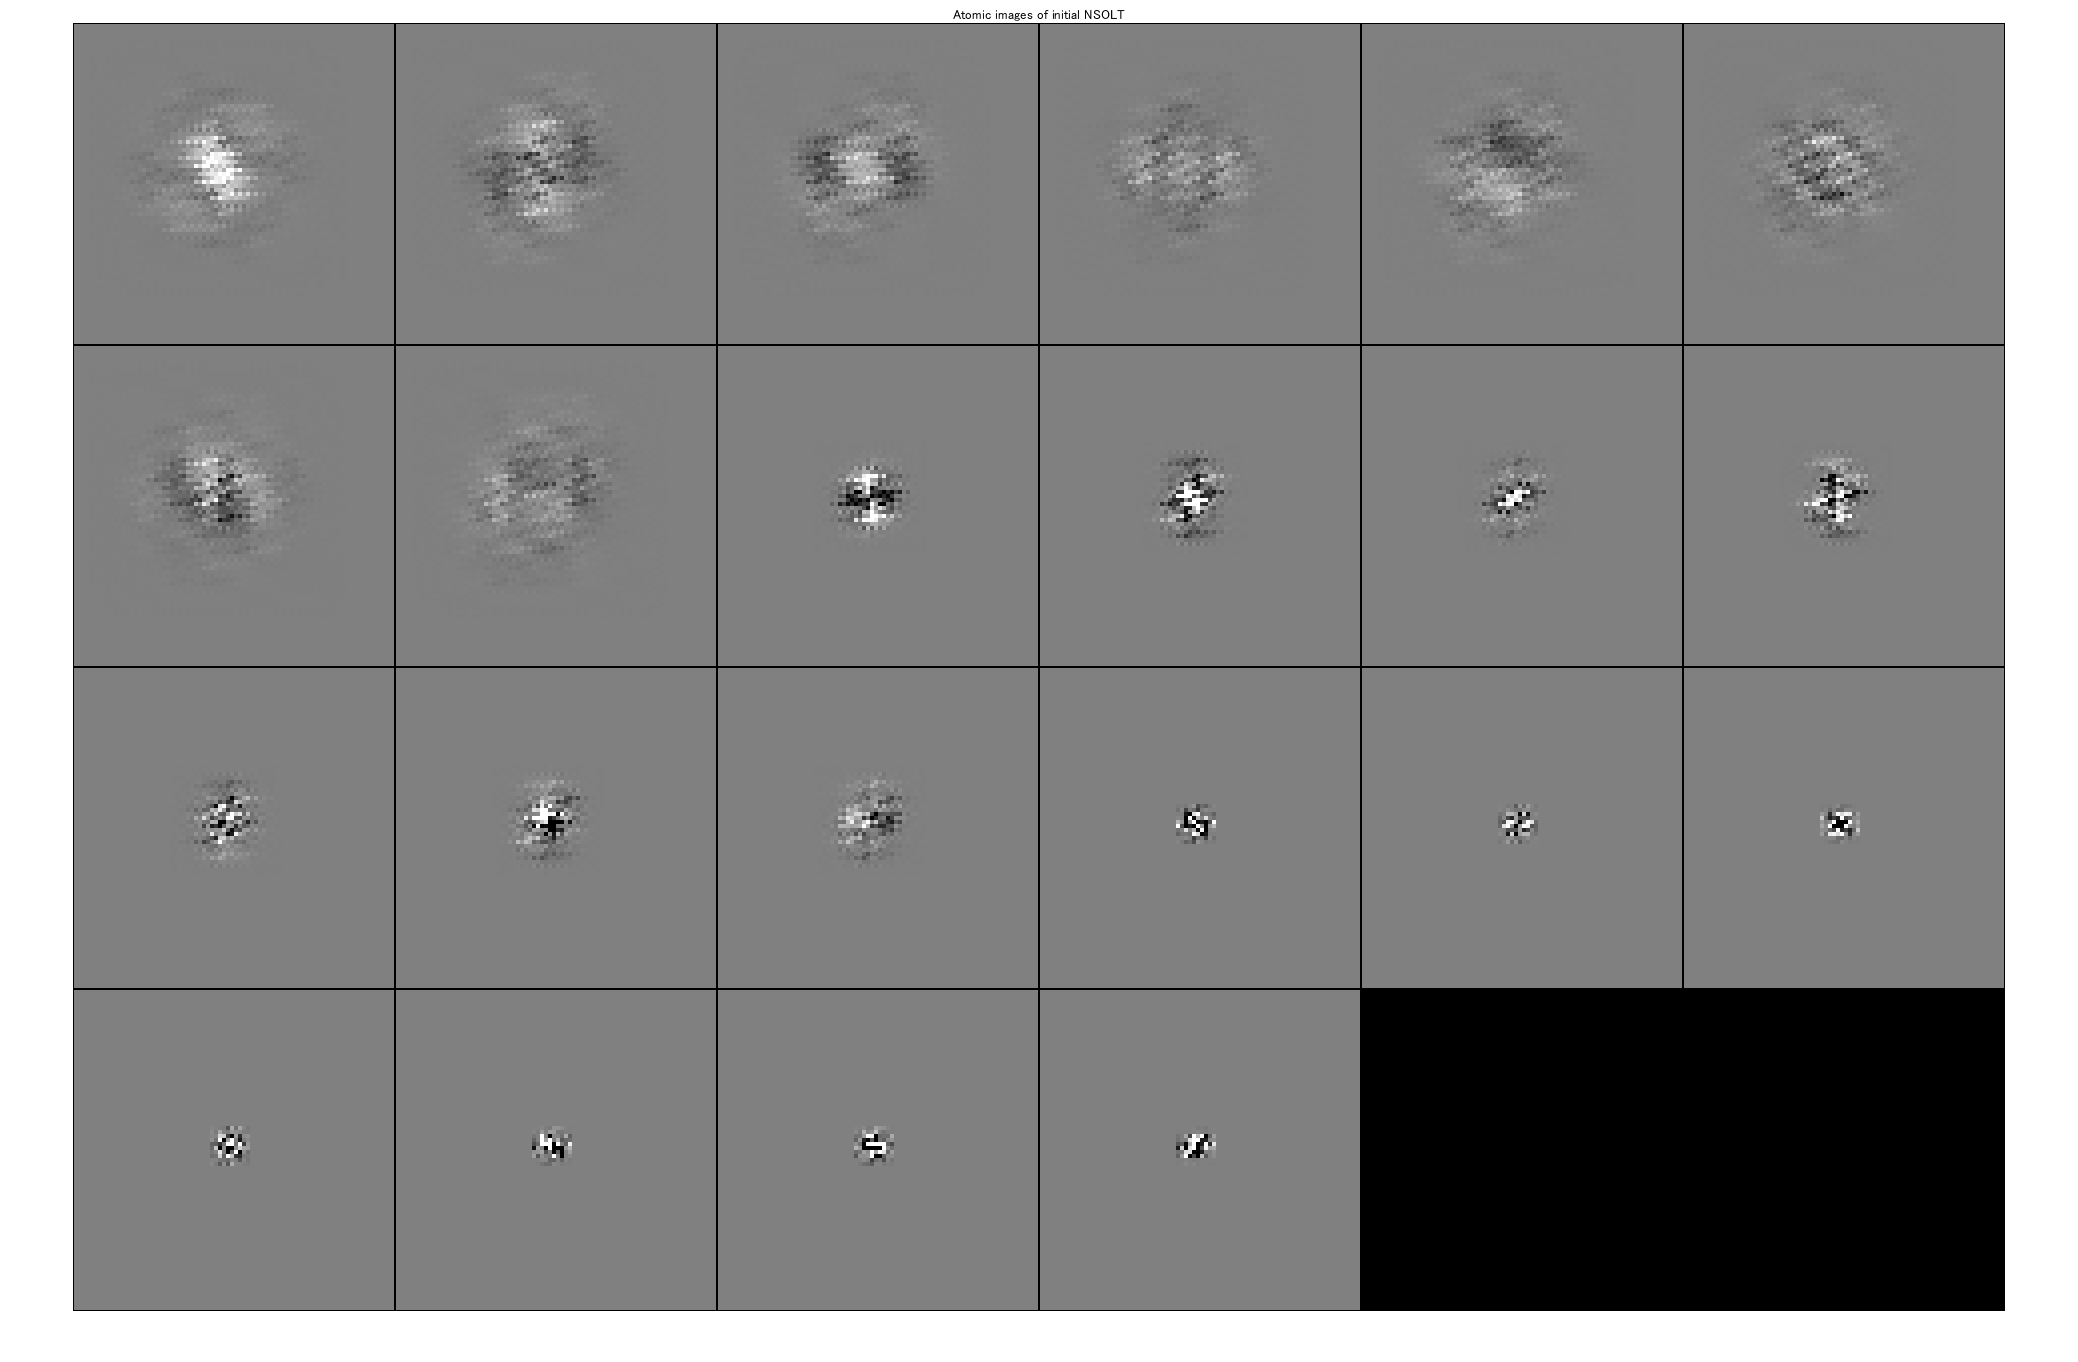

figure(4)
imshowscale = sum(nChannels);
atomicimshow(synthesisnet,[],imshowscale)
title('Atomic images of initial NSOLT')

### Preparation of traning image

Randomly extracting patches from the image data store

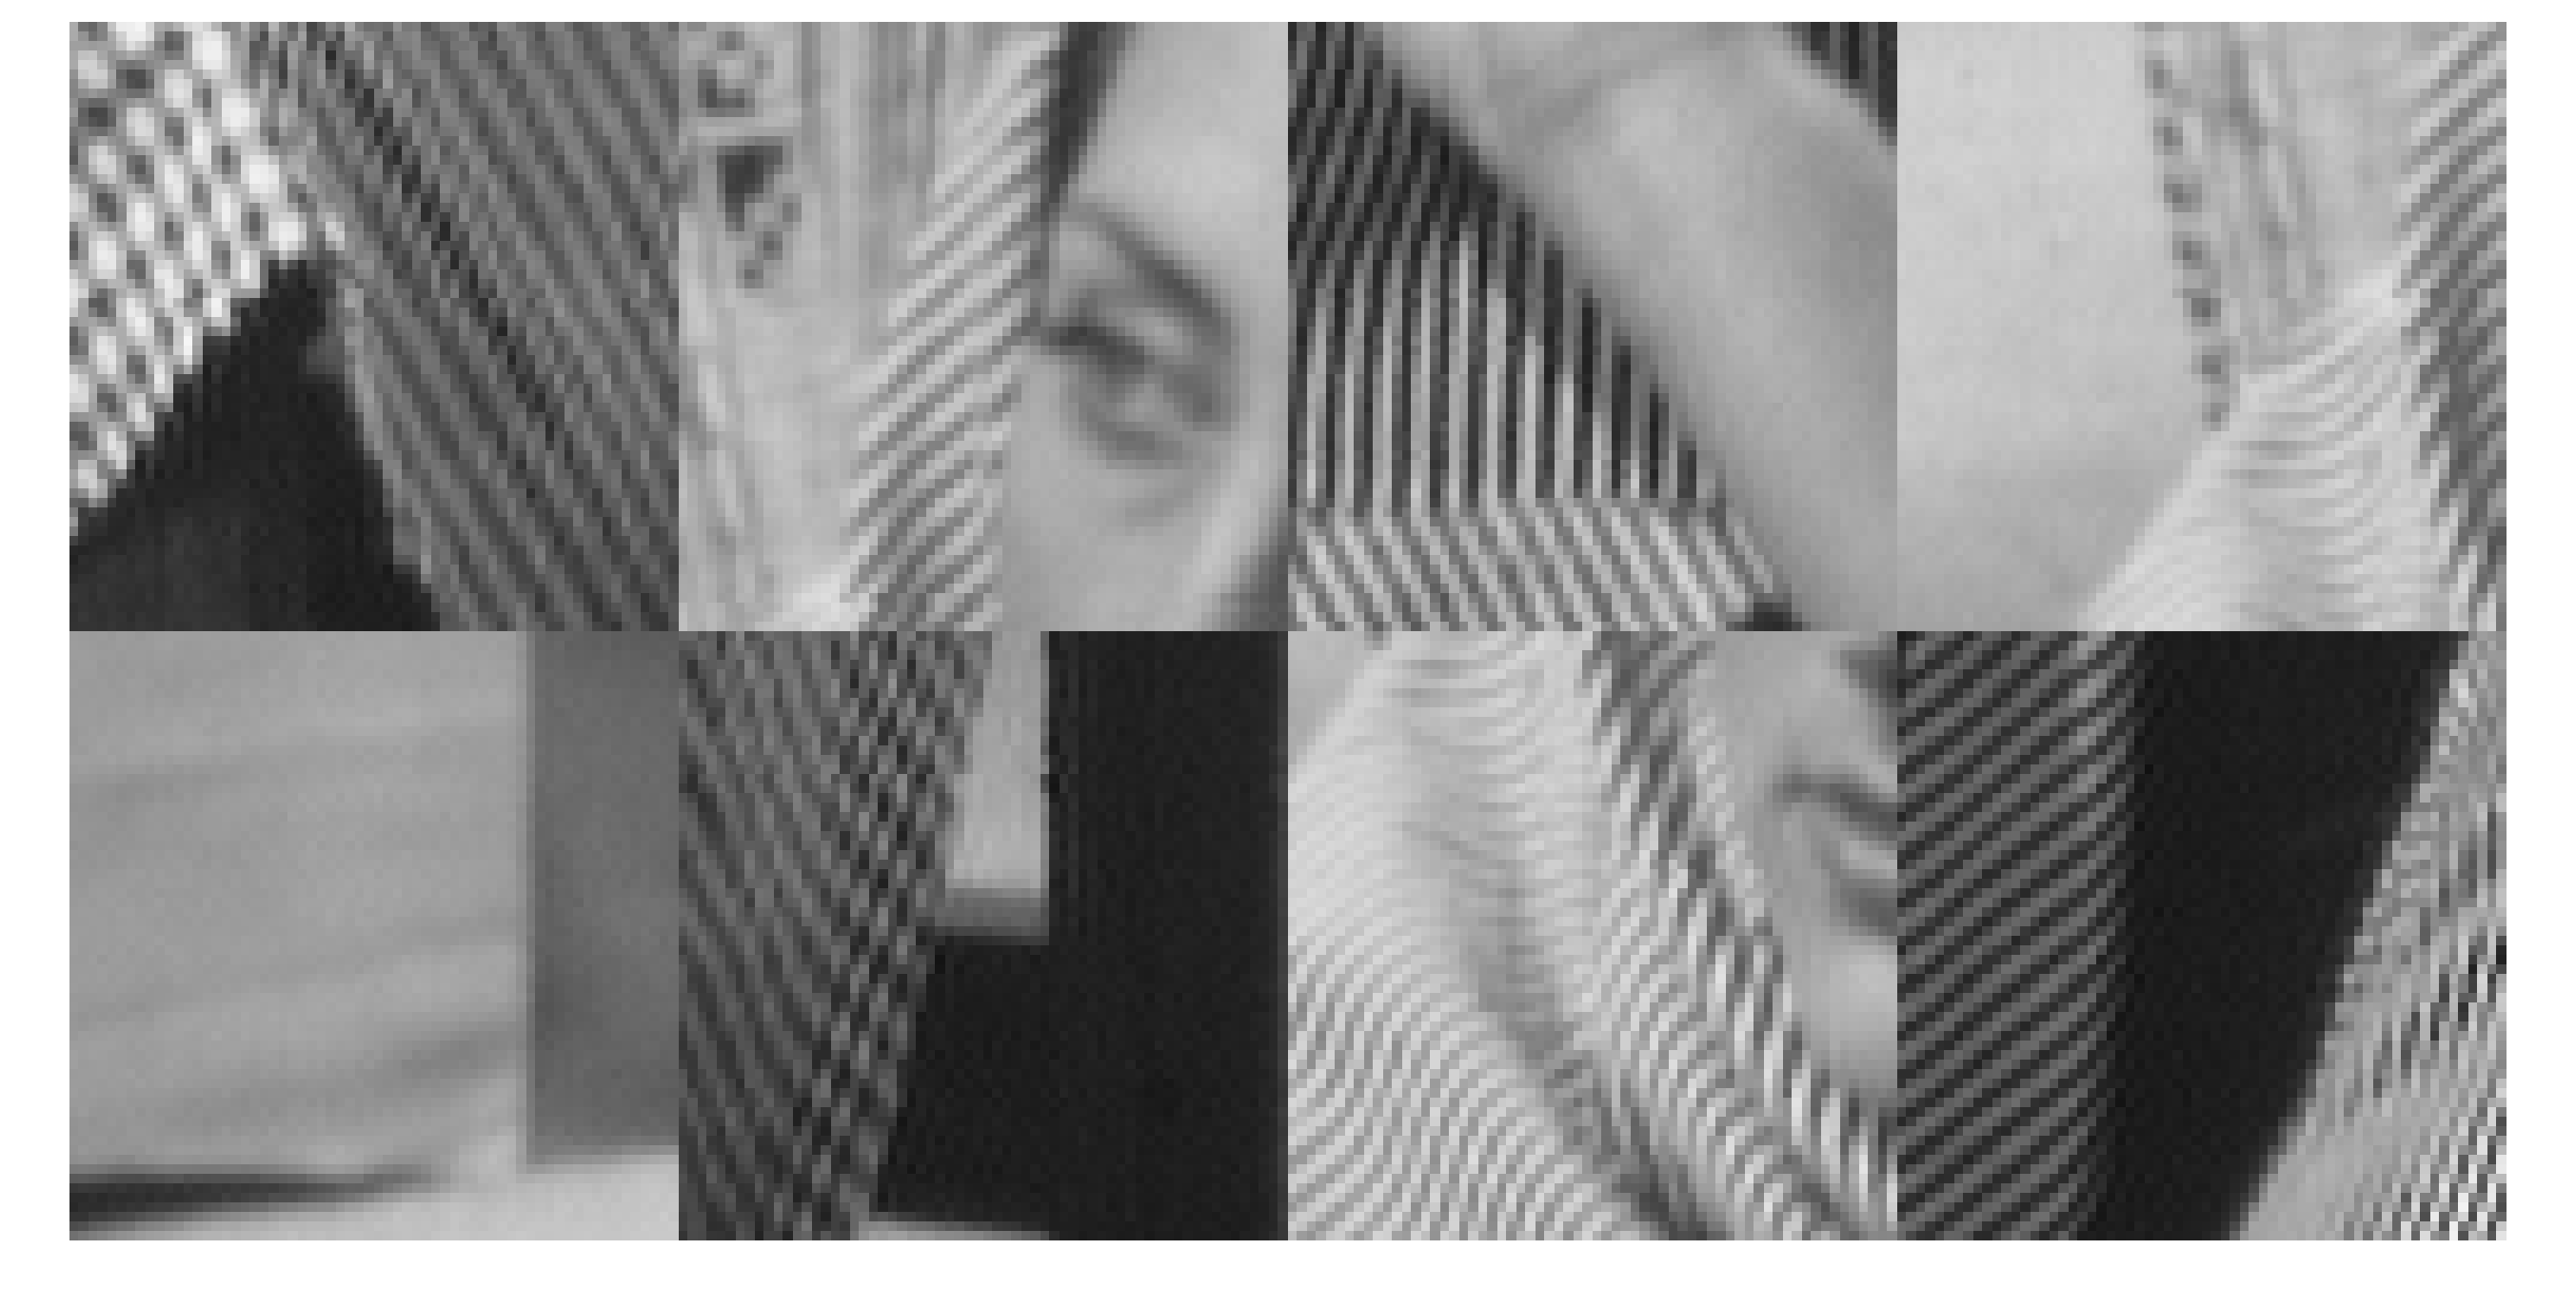

imds = imageDatastore("./data/barbara.png","ReadFcn",@(x) im2single(imread(x)));
patchds = randomPatchExtractionDatastore(imds,imds,szPatchTrn,'PatchesPerImage',nSubImgs);
figure(5)
minibatch = preview(patchds);
responses = minibatch.ResponseImage;
montage(responses,'Size',[2 4]);

### Convolutional dictionary learning

#### Problem setting:

    
$$\{\hat{\mathbf{\theta}},\{ \hat{\mathbf{s}}_n \}\}=\arg\min_{\{\mathbf{\theta},\{\mathbf{s}_n\}\}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{v}_n-\mathbf{D}_{\mathbf{\theta}}\hat{\mathbf{s}}_n\|_2^2,\ \quad\mathrm{s.t.}\ \forall n, \|\mathbf{s}_n\|_0\leq K,$$$


where $\mathbf{D}_{\mathbf{\theta}}$ is a convolutional dictionary with the design parameter vector $\mathbf{\theta}}$.

#### Algorithm:

Iterate the sparse approximation step and the dictionary update step.

- Sparse approximation step

                
$$\hat{\mathbf{s}}_n=\arg\min_{\mathbf{s}_n}\frac{1}{2} \|\mathbf{v}_n-\hat{\mathbf{D}}\mathbf{s}_n\|_2^2\ \quad \mathrm{s.t.}\ \|\mathbf{s}_n\|_0\leq K$$


- Dictionary update step

                
$$\hat{\mathbf{\theta}}=\arg\min_{\mathbf{\theta}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{v}_n-\mathbf{D}_{\mathbf{\theta}}\hat{\mathbf{s}}_n\|_2^2$$


                
$$\hat{\mathbf{D}}=\mathbf{D}_{\hat{\mathbf{\theta}}$$


#### Alternate iteration of sparse approximation step and dictioary update step

- Sparse approximation：Iterative hard thresholding

- Dictionary update： Stochastic gradient descent w/ momentum

% Check if IHT works for dlarray
%x = dlarray(randn(szPatchTrn,'single'),'SSCB');
%[y,coefs{1:nOutputs}] = iht(x,analysisnet,synthesisnet,sparsityRatio);

Iterative calculation of alternative steps

%profile on
for iIter = 1:nIters
    
    % Sparse approximation (Applied to produce an object of TransformedDatastore)
    coefimgds = transform(patchds, @(x) iht4inputimage(x,analysisnet,synthesisnet,sparsityRatio));

    % Synthesis dictionary update
    trainlgraph = synthesislgraph.replaceLayer('Lv1_Out',...
        regressionLayer('Name','Lv1_Out'));
    trainednet = trainNetwork(coefimgds,trainlgraph,opts);

    % Analysis dictionary update (Copy parameters from synthesizer to analyzer)
    trainedlgraph = layerGraph(trainednet);
    analysislgraph = fcn_cpparamssyn2ana(analysislgraph,trainedlgraph);
    analysisnet = dlnetwork(analysislgraph);

    % Check the adjoint relation (perfect reconstruction)
    checkadjointrelation(analysislgraph,trainedlgraph,nLevels,szPatchTrn);

    % Replace layer
    synthesislgraph = trainedlgraph.replaceLayer('Lv1_Out',...
        nsoltIdentityLayer('Name','Lv1_Out'));
    synthesisnet = dlnetwork(synthesislgraph);
    
end
%profile off
%profile viewer

単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：２７　｜　　　　　　　　　４．５５　｜　　　　　　１０．４　｜　　０．０１００　｜
｜　　　　　　８　｜　　　３２　｜　　　　　００：０２：２７　｜　　　　　　　　　４．３７　｜　　　　　　　９．５　｜　　０．０１００　｜
｜　　　　　１６　｜　　　６４　｜　　　　　００：０４：４１　｜　　　　　　　　　４．５６　｜　　　　　　１０．４　｜　　０．０１００　｜
｜　　　　　２４　｜　　　９６　｜　　　　　００：０６：５５　｜　　　　　　　　　４．５２　｜　　　　　　１０．２　｜　　０．０１００　｜
｜　　　　　３２　｜　　１２８　｜　　　　　００：０９：０９　｜　　　　　　　　　４．３７　｜　　　　　　　９．６　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 1.6164e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：２７　｜　　　　　　　　　３．９３　｜　　　　　　　７．７　｜　　０．０１００　｜
｜　　　　　　８　｜　　　３２　｜　　　　　００：０２：２７　｜　　　　　　　　　３．６５　｜　　　　　　　６．６　｜　　０．０１００　｜
｜　　　　　１６　｜　　　６４　｜　　　　　００：０４：３６　｜　　　　　　　　　３．３１　｜　　　　　　　５．５　｜　　０．０１００　｜
｜　　　　　２４　｜　　　９６　｜　　　　　００：０６：４０　｜　　　　　　　　　３．６５　｜　　　　　　　６．７　｜　　０．０１００　｜
｜　　　　　３２　｜　　１２８　｜　　　　　００：０８：４７　｜　　　　　　　　　３．９９　｜　　　　　　　８．０　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 1.6996e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：２７　｜　　　　　　　　　３．３４　｜　　　　　　　５．６　｜　　０．０１００　｜
｜　　　　　　８　｜　　　３２　｜　　　　　００：０２：２７　｜　　　　　　　　　３．１４　｜　　　　　　　４．９　｜　　０．０１００　｜
｜　　　　　１６　｜　　　６４　｜　　　　　００：０４：４３　｜　　　　　　　　　３．６５　｜　　　　　　　６．６　｜　　０．０１００　｜
｜　　　　　２４　｜　　　９６　｜　　　　　００：０７：０１　｜　　　　　　　　　３．７１　｜　　　　　　　６．９　｜　　０．０１００　｜
｜　　　　　３２　｜　　１２８　｜　　　　　００：０９：２０　｜　　　　　　　　　３．６０　｜　　　　　　　６．５　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 2.3534e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：２８　｜　　　　　　　　　３．８１　｜　　　　　　　７．３　｜　　０．０１００　｜
｜　　　　　　８　｜　　　３２　｜　　　　　００：０２：３２　｜　　　　　　　　　３．５８　｜　　　　　　　６．４　｜　　０．０１００　｜
｜　　　　　１６　｜　　　６４　｜　　　　　００：０４：５１　｜　　　　　　　　　３．８８　｜　　　　　　　７．５　｜　　０．０１００　｜
｜　　　　　２４　｜　　　９６　｜　　　　　００：０７：０９　｜　　　　　　　　　４．１３　｜　　　　　　　８．５　｜　　０．０１００　｜
｜　　　　　３２　｜　　１２８　｜　　　　　００：０９：２８　｜　　　　　　　　　３．６３　｜　　　　　　　６．６　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 2.5599e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：２７　｜　　　　　　　　　３．９３　｜　　　　　　　７．７　｜　　０．０１００　｜
｜　　　　　　８　｜　　　３２　｜　　　　　００：０２：２７　｜　　　　　　　　　３．３５　｜　　　　　　　５．６　｜　　０．０１００　｜
｜　　　　　１６　｜　　　６４　｜　　　　　００：０４：４１　｜　　　　　　　　　３．６２　｜　　　　　　　６．５　｜　　０．０１００　｜
｜　　　　　２４　｜　　　９６　｜　　　　　００：０６：５５　｜　　　　　　　　　３．８４　｜　　　　　　　７．４　｜　　０．０１００　｜
｜　　　　　３２　｜　　１２８　｜　　　　　００：０９：０９　｜　　　　　　　　　３．１１　｜　　　　　　　４．８　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 1.6715e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：２７　｜　　　　　　　　　３．０８　｜　　　　　　　４．７　｜　　０．０１００　｜
｜　　　　　　８　｜　　　３２　｜　　　　　００：０２：２６　｜　　　　　　　　　３．３３　｜　　　　　　　５．５　｜　　０．０１００　｜
｜　　　　　１６　｜　　　６４　｜　　　　　００：０４：４０　｜　　　　　　　　　３．４５　｜　　　　　　　５．９　｜　　０．０１００　｜
｜　　　　　２４　｜　　　９６　｜　　　　　００：０６：５４　｜　　　　　　　　　３．０８　｜　　　　　　　４．７　｜　　０．０１００　｜
｜　　　　　３２　｜　　１２８　｜　　　　　００：０９：０８　｜　　　　　　　　　３．１５　｜　　　　　　　５．０　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 1.3326e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：２７　｜　　　　　　　　　２．９３　｜　　　　　　　４．３　｜　　０．０１００　｜
｜　　　　　　８　｜　　　３２　｜　　　　　００：０２：２６　｜　　　　　　　　　３．８７　｜　　　　　　　７．５　｜　　０．０１００　｜
｜　　　　　１６　｜　　　６４　｜　　　　　００：０４：４０　｜　　　　　　　　　３．２４　｜　　　　　　　５．３　｜　　０．０１００　｜
｜　　　　　２４　｜　　　９６　｜　　　　　００：０６：５４　｜　　　　　　　　　３．１６　｜　　　　　　　５．０　｜　　０．０１００　｜
｜　　　　　３２　｜　　１２８　｜　　　　　００：０９：０８　｜　　　　　　　　　３．１０　｜　　　　　　　４．８　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 1.792e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：２７　｜　　　　　　　　　３．２１　｜　　　　　　　５．１　｜　　０．０１００　｜
｜　　　　　　８　｜　　　３２　｜　　　　　００：０２：２６　｜　　　　　　　　　３．０９　｜　　　　　　　４．８　｜　　０．０１００　｜
｜　　　　　１６　｜　　　６４　｜　　　　　００：０４：４０　｜　　　　　　　　　３．２３　｜　　　　　　　５．２　｜　　０．０１００　｜
｜　　　　　２４　｜　　　９６　｜　　　　　００：０６：５３　｜　　　　　　　　　３．１３　｜　　　　　　　４．９　｜　　０．０１００　｜
｜　　　　　３２　｜　　１２８　｜　　　　　００：０８：５７　｜　　　　　　　　　３．４３　｜　　　　　　　５．９　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 2.6768e-14"



### The atomic images of trained dictionary

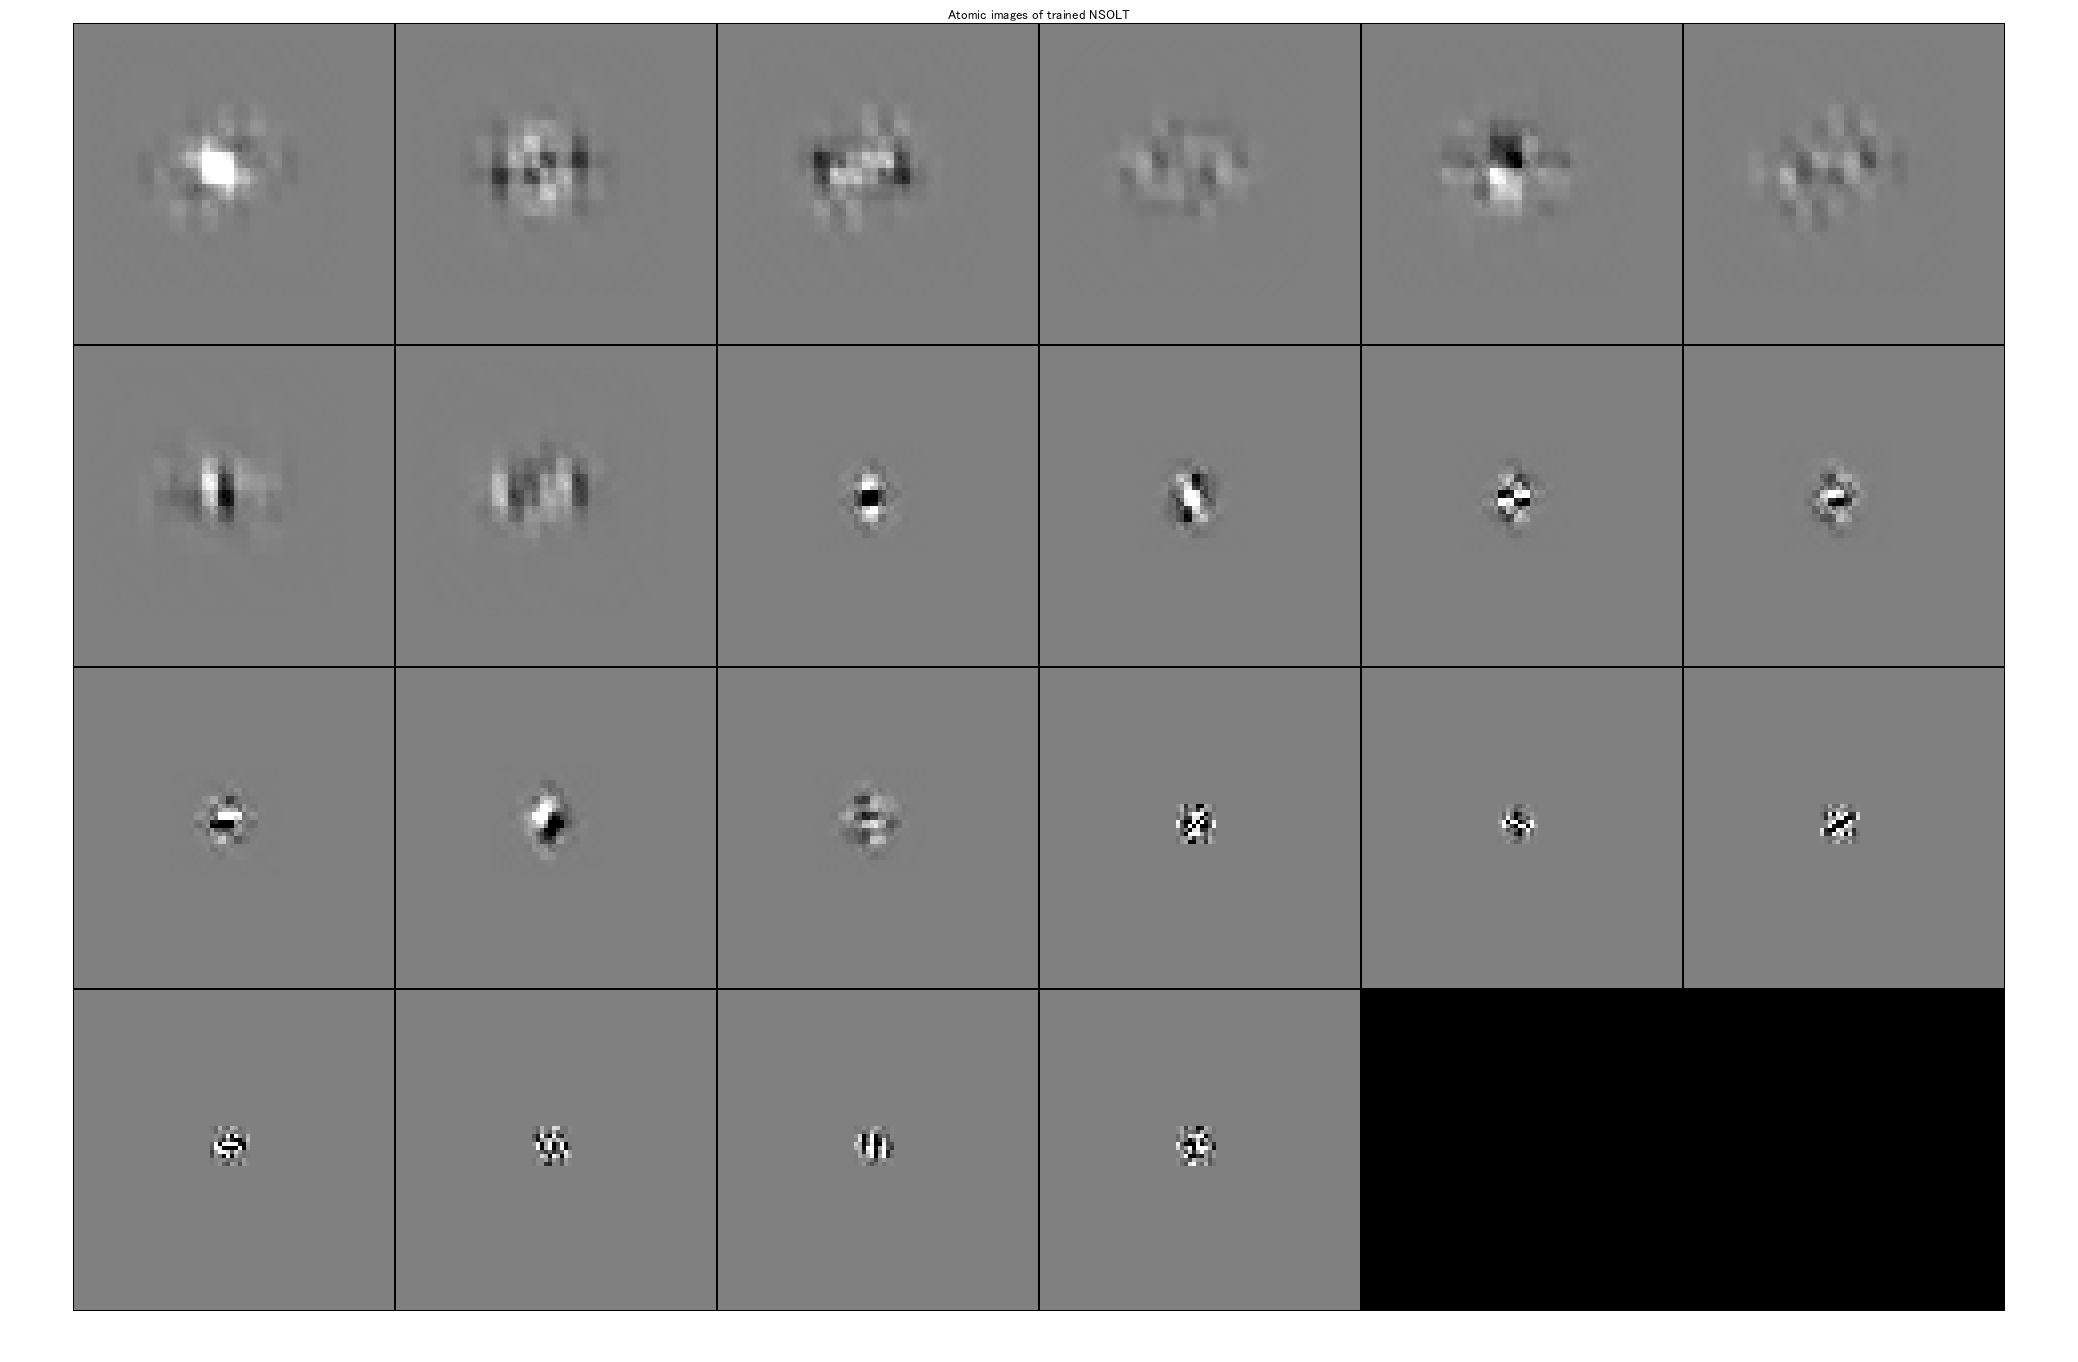

import saivdr.dcnn.*
figure(6)
imshowscale = sum(nChannels);
atomicimshow(synthesisnet,[],imshowscale)
title('Atomic images of trained NSOLT')

### Save the designed network

import saivdr.dcnn.*
% Construction of analysis network
synthesislgraph = layerGraph(synthesisnet);
analysislgraph = fcn_cpparamssyn2ana(analysislgraph,synthesislgraph);

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

analysisnet = dlnetwork(analysislgraph);
save(sprintf('./data/nsoltdictionary_%s',datetime('now','Format','yyyyMMddhhmmssSSS')),'analysisnet','synthesisnet')

### Function of iterative hard thresholding

The input images of the patch pairs are replaced with sparse coefficients obtained by IHT, where normalization is omitted for the Parseval tight property of NSOLT ( $\mathbf{DD}^T=\mathbf{I}$ ).

         
$$\mathbf{s}^{(t+1)}\leftarrow \mathcal{H}_{T_K}\left(\mathbf{s}^{(t)}-\gamma \hat{\mathbf{D}}^T\left(\hat{\mathbf{D}}\mathbf{s}^{(t)}-\mathbf{v}\right)\right)$$


        
$$t\leftarrow t+1$$


where

        
$$[\mathcal{H}_{T_K}(\mathbf{x})]_i=\left\{\begin{array}{ll} 0 , & |[\mathbf{x}]_i| \leq T_K \\ [\mathbf{x}]_i, & |[\mathbf{x}]_i|> T_K \end{array}\right.$$


【Reference】

-  T. Blumensath and M. E. Davies, "Normalized Iterative Hard Thresholding: Guaranteed Stability and Performance," in IEEE Journal of Selected Topics in Signal Processing, vol. 4, no. 2, pp. 298-309, April 2010, doi: 10.1109/JSTSP.2010.2042411.

function newdata = iht4inputimage(oldtbl,analyzer,synthesizer,sparsityRatio)
% IHT for InputImage in randomPatchExtractionDatastore
%
nInputs = length(synthesizer.InputNames);

% Apply IHT process for every input patch
restbl = removevars(oldtbl,'InputImage');
dlv = dlarray(cat(4,oldtbl.InputImage{:}),'SSCB');
[~,dlcoefs{1:nInputs}] = iht(dlv,analyzer,synthesizer,sparsityRatio);
coefs = cellfun(@(x) permute(num2cell(extractdata(x),1:3),[4 1 2 3]),dlcoefs,'UniformOutput',false);
%
nImgs = length(oldtbl.InputImage);
coefarray = cell(nImgs,nInputs);
for iImg = 1:nImgs
    for iInput = 1:nInputs
        coefarray{iImg,iInput} = coefs{iInput}{iImg};
    end
end
% Output as a cell in order to make multiple-input datastore
newdata = [ coefarray table2cell(restbl) ];
end

function [dly,varargout] = iht(dlx,analyzer,synthesizer,sparsityRatio)
% IHT Iterative hard thresholding
%
nInputs = length(synthesizer.InputNames);
szBatch = size(dlx,4);

% Iterative hard thresholding w/o normalization
% (A Parseval tight frame is assumed)
gamma = (1.-1e-3);
nIters = 10;
nCoefs = floor(sparsityRatio*numel(dlx(:,:,:,1)));
[dlcoefs{1:nInputs}] = analyzer.predict(dlarray(zeros(size(dlx),'like',dlx),'SSCB'));
% IHT
for iter=1:nIters
    % Gradient descent
    dly = synthesizer.predict(dlcoefs{1:nInputs});
    [grad{1:nInputs}] = analyzer.predict(dly-dlx);
    dlcoefs = cellfun(@(x,y) x-gamma*y,dlcoefs,grad,'UniformOutput',false);
    % Hard thresholding
    coefvecs = cellfun(@(x) extractdata(reshape(x,[],szBatch)),dlcoefs,'UniformOutput',false);
    srtdabscoefs = sort(abs(cell2mat(coefvecs.')),1,'descend');
    thk = reshape(srtdabscoefs(nCoefs,:),1,1,1,szBatch);
    dlcoefs = cellfun(@(x) (abs(x)>thk).*x,dlcoefs,'UniformOutput',false);
    % Monitoring
    %checkSparsity =...
    %nnz(srtdabscoefs>srtdabscoefs(nCoefs,:))/numel(dlx)<=sparsityRatio;
    %assert(checkSparsity)
    %fprintf("IHT(%d) MSE: %6.4f\n",iter,mse(dlx,dly));
end
varargout = dlcoefs;
end

function checkadjointrelation(analysislgraph,synthesislgraph,nLevels,szInput)
import saivdr.dcnn.*
x = rand(szInput,'single');
% Assemble analyzer
analysislgraph4predict = analysislgraph;
for iLayer = 1:length(analysislgraph4predict.Layers)
    layer = analysislgraph4predict.Layers(iLayer);
    if contains(layer.Name,"Lv"+nLevels+"_DcOut") || ...
            ~isempty(regexp(layer.Name,'^Lv\d+_AcOut','once'))
        analysislgraph4predict = analysislgraph4predict.replaceLayer(layer.Name,...
            regressionLayer('Name',layer.Name));
    end
end
analysisnet4predict = assembleNetwork(analysislgraph4predict);

% Assemble synthesizer
synthesislgraph4predict = synthesislgraph;
synthesisnet4predict = assembleNetwork(synthesislgraph4predict);

% Analysis and synthesis process
[s{1:nLevels+1}] = analysisnet4predict.predict(x);
if isvector(s{end-1})
    s{end-1} = permute(s{end-1},[1,3,2]);
end
y = synthesisnet4predict.predict(s{:});

% Evaluation
display("MSE: " + num2str(mse(x,y)))
end

© Copyright, Shogo MURAMATSU, All rights reserved.